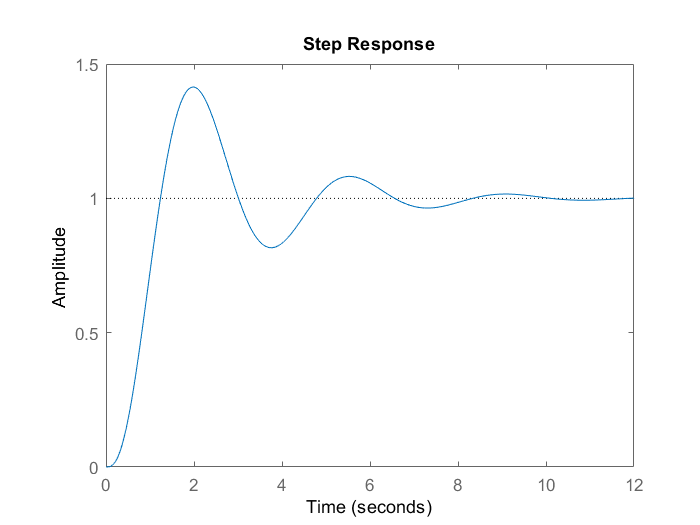

ans = struct with fields:
        RiseTime: 0.7514
    SettlingTime: 7.8960
     SettlingMin: 0.8162
     SettlingMax: 1.4143
       Overshoot: 41.4292
      Undershoot: 0
            Peak: 1.4143
        PeakTime: 1.9746


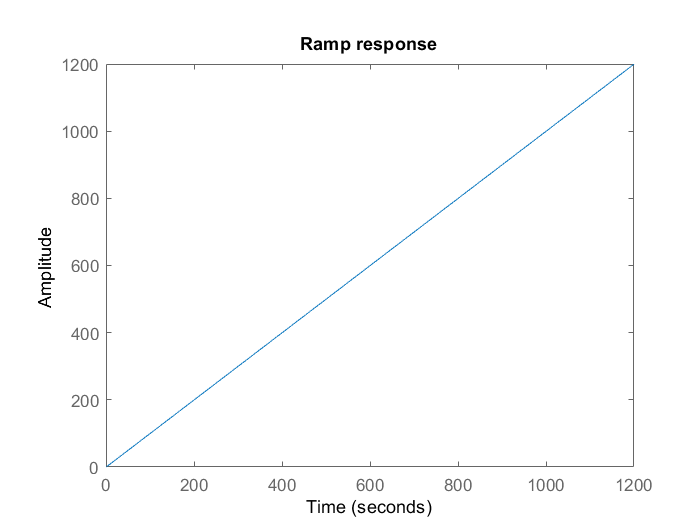

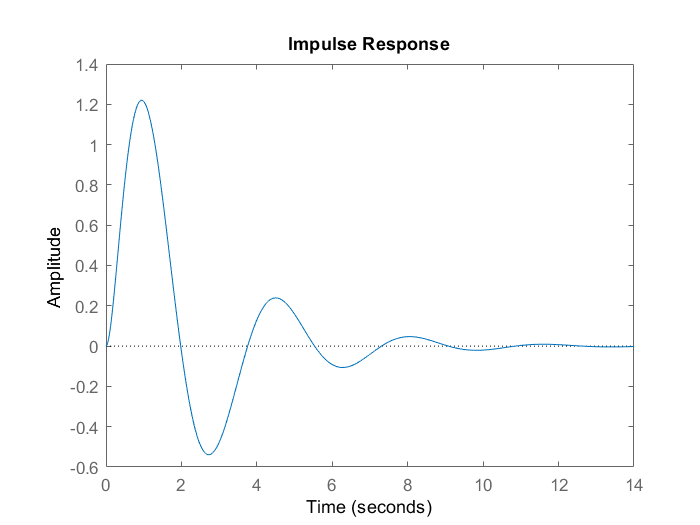

%System response 

s=tf('s');
%last 2 digit of my roll=17
G=17/(s*(s+2)*(s+4)); 
F=feedback(G,1);
%step response
step(F)
% rise time, peak time, maximum overshoot, and settling time 
stepinfo(F)
%ramp response
step(F/s)
title('Ramp response')
%impulse response
impulse(F)